### Init and load torque from excel:

clear
load("airfoil.mat")
load("wing_opt.mat")
load("scr_s0.mat")
load("Farror.mat")
T = readtable("E - Wing Load.xlsx",'Sheet',"Wing Torque");

location = table2array(T(1:60,3));
M = table2array(T(1:60,25))*1e-3;
location = [-flip(location); location(2:end)];
M0 = [flip(M); M(2:end)];
M_interpolated = interp1(location, M0, wing_opt.stripy,'spline');
M = M_interpolated;
pltidx=1

pltidx = 1

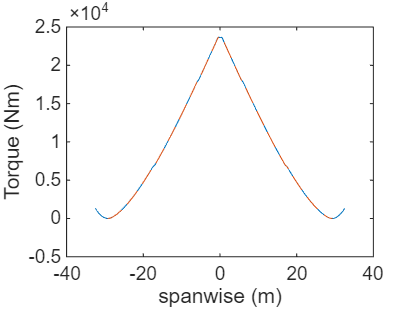

figure(pltidx)
clf;
plot(wing_opt.stripy, M)
hold on
plot(location, M0,'--')
xlabel("spanwise (m)")
ylabel("Torque (Nm)")

pltidx = pltidx + 1;

Material:

steel=material();
steel.E = 70e9;

## **WingBox geometry (unchanged throughout)**

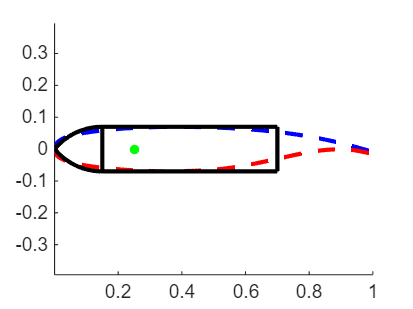

wb = wingbox();
%define geometry
wb.b2_c = 0.14;
wb.b_c = 0.15;
wb.c_c = 0.7 - wb.b_c;
wb = wb.calcR();
%define stringers
wb.L = 1;
%show wingbox:
figure(pltidx)
clf;
wb.drawwithAirfoil(airfoil)

pltidx = pltidx + 1;

## 1.skin buckling, variables are:

wb.N = 20;        % stringer number
wb.ts = 10e-3;    % stringer thickness
wb.hs = 80e-3;    % stringer height
wb.ds = wb.hs*0.3;% stringer width
wb = wb.calcb1();
wb = wb.calcStringerArea();

wb.t2 = 7.72e-3; % main cell thickness

Compute critical stresses (global and local)

wb = wb.interpsr_s0(scr_s0,wing_opt);
wb = wb.interpretF(F_data, wing_opt);

wbStress = wingboxStress();
wbStress.wb = wb;
wbStress = wbStress.findGlobalStress(M,wing_opt,steel);
wbStress = wbStress.findLocalStress(M,wing_opt,steel);

Thickness parameters need to be optimized to give equal global and local buckling stress

figure(pltidx)
pltidx = pltidx + 1;
clf;
hold on
plot(wing_opt.stripy, wbStress.s_cr_global_skin);
hold on
plot(wing_opt.stripy, wbStress.s_cr_local_skin);

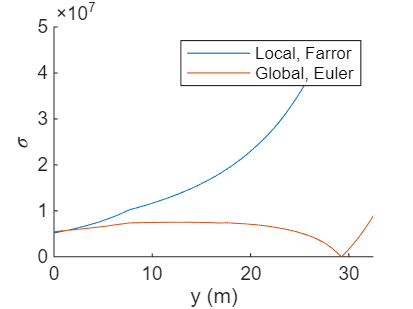

legend("Local, Farror","Global, Euler")
xlabel("y (m)")
ylabel("$\sigma$","Interpreter","latex")
xlim([0 wing_opt.s])